## SVM with CVX

Suppose that we are given 40 points in the plane. Each of these points belongs to one of two calsses. Specifically, there are 19 points of class 1 and 21 points of class 2. The points are generated and plotted by the MATLAB commands

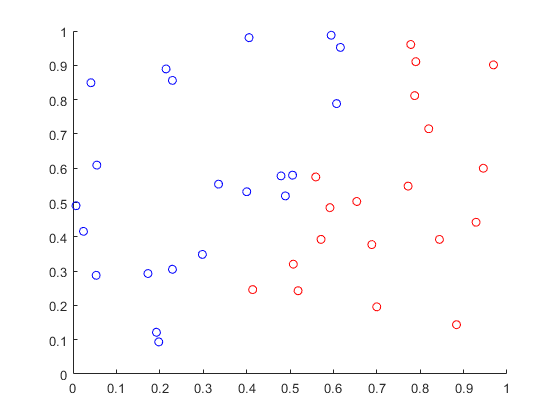

rand('seed', 314);
x = rand(40,1);
y = rand (40,1);
class = [2*x<y+0.5] + 1;
A1 = [x(find(class==1)), y(find(class==1))]; 
A2 = [x(find(class==2)), y(find(class == 2))];
X = [A1 ; A2];
Y = [ones(length(A1), 1); -ones(length(A2),1)];
figure;
xlim([0 1])
ylim([0 1])
hold on 
scatter(A1(:, 1), A1(:, 2), 'ro'); % Class 1 data points
scatter(A2(:, 1), A2(:, 2), 'bo'); % Class 2 data points

Write a CVX_based code for finding the maximum_margin line seprating the two classes of points.

for solving this problem we know that this problem is equivalence to below minimization problem:

                                                                                                                    
$$\begin{array}{l}
\mathrm{min}\;\;\frac{1}{2}||w||^2 \\
s\ldotp t\ldotp \;\;\;|w^T x_i +\beta |\ge 1,\;\;\;\;i=1,2,\ldotp \ldotp \ldotp ,m,\;m+1,\ldotp \ldotp \ldotp ,m+p\ldotp 
\end{array}$$


where 

                                                                                                                     
$$m=\mathrm{length}\left(A_1 \right),p=\mathrm{length}\left(A_2 \right)$$


so we have:

cvx_begin
    variables w(2) b(1)
    minimize(1/2*square_pos(norm(w)))
    subject to
        Y .* (X * w + b) >= 1
cvx_end

 
Calling SDPT3 4.0: 48 variables, 7 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  7
 dim. of sdp    var  =  2,   num. of sdp  blk  =  1
 dim. of socp   var  =  3,   num. of socp blk  =  1
 dim. of linear var  = 42
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|9.8e+00|4.4e+03|-3.900000e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.074|0.094|5.1e+01|8.9e+00|4.2e+03|-4.087024e+02 -8.780319e-01| 0:0:00| chol  1  1 
 2|0.489|0.490|2.6e+01|4.5e+00|2.6e+03|-3.354694e+02 -8.801261e+00| 0:0:00

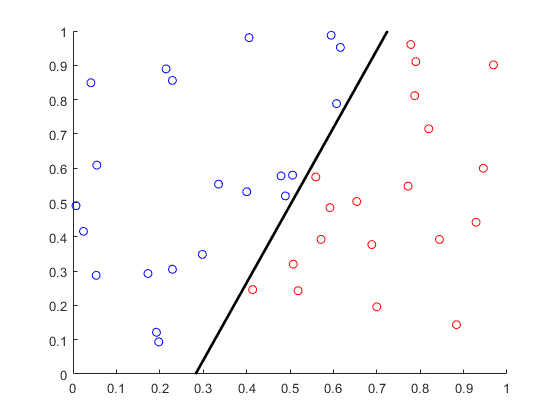

% Extracting w and beta
w = w(:);
b = b(:);
% Plot seprating line  
figure;
xlim([0 1])
ylim([0 1])
hold on;
scatter(A1(:, 1), A1(:, 2), 'ro'); % Class 1 data points
scatter(A2(:, 1), A2(:, 2), 'bo'); % Class 2 data points
line_x = linspace(min(X(:, 1)), max(X(:, 1)), 100);
line_y = (-w(1) * line_x - b) / w(2);
plot(line_x, line_y, 'k-', 'LineWidth', 2); % SVM hyperplane
hold off